# Hour power 2

### List of good data for each channel

Channel 1 and channel 2

48 hour days - currently excluding 48 hour data

%channel 1
goodkgidx1 = [1 2 54 6 7 8 101 9 99 10 11 12 14 15 16 19 27 31 100 28 30 33 35 36 37 38 39 40 41 42 54 56];

    for j = 1:length(goodkgidx1)
      gk1(j).trial1 = KatieTrialDessembler(kg(goodkgidx1(j)), 1, goodkgidx1(j));
    end
    
    for j = length(gk1):-1:1
        for jj = 1:length(gk1(j).trial1)
       [gk1(j).freq1(jj), gk1(j).pwr1(jj)] = k_welches(gk1(j).trial1(jj), gk1(j).trial1(jj).ld, 10);
       gk1(j).hour1(jj) = gk1(j).trial1(jj).ld;
        end
    end


%channel 2
goodkgidx2 = [1 55 6 7 10 11 12 14 15 16 19 30 31 28 33 35 36 37 38 39 40 41 42 47 98 55 57 97];

    for j = 1:length(goodkgidx2)
      gk2(j).trial2 = KatieTrialDessembler(kg(goodkgidx2(j)), 1, goodkgidx2(j));
    end
    
    for j = length(gk2):-1:1
        for jj = 1:length(gk2(j).trial2)
       [gk2(j).freq2(jj), gk2(j).pwr2(jj)] = k_welches(gk2(j).trial2(jj), gk2(j).trial2(jj).ld, 10);
       gk2(j).hour2(jj) = gk2(j).trial2(jj).ld;
        end
    end
    

# Plots

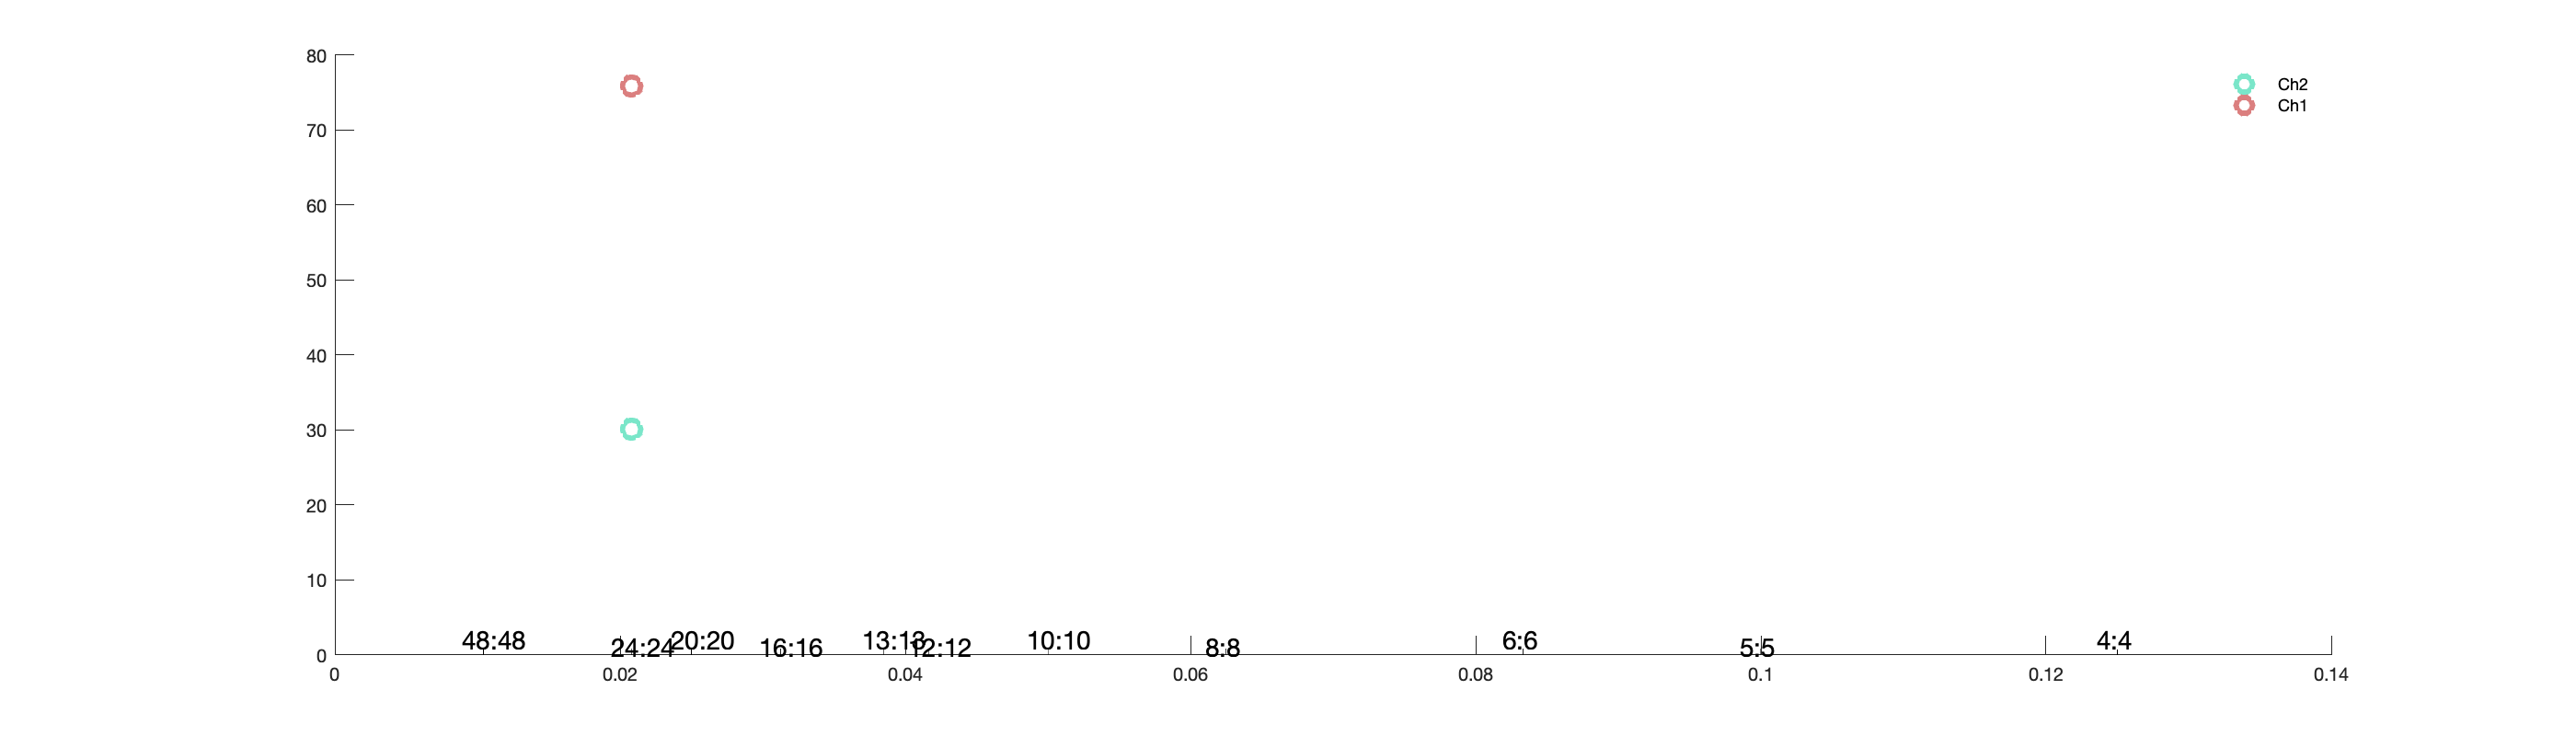

%colors for plots
rosey = [.8588 0.4980 0.4980];
aqua = [0.4784 0.9020 0.7882];
        
%size of figure window
L = 2*200;
W = 2*700; %changed from 2*420

close all; figure(1); clf; hold on; title('power at daylength in hours');
%set(figure(1),'Units','normalized','Position',[0 0 .5 .5]); 
    set(gcf, 'Position', [0 0 W L]);

    %get ylim variables
    %maxY
    
        maxY = max(pwr1);
        minY = min(pwr2);
   
    %Draw lines for light cycles
    hrs = [96, 48, 40, 32, 26, 24, 20, 16, 12, 10, 8]; % Double hours

    %plot data on log scale
    %fftmachine
    
    figure(1); clf; hold on;
    for j = length(gk2)
        for jj = length(gk2(j).freq2)
    plot(gk2(j).freq2(jj), gk2(j).pwr2(jj), 'o', 'Color', aqua, 'MarkerSize', 10, "LineWidth", 3); hold on;
        end
    end
    for j = length(gk1)
        for jj = length(gk1(j).freq1)
          plot(gk1(j).freq1(jj), gk1(j).pwr1(jj), 'o', 'Color', rosey, 'MarkerSize', 10, "LineWidth", 3);  %ylim([minY, maxY + 0.01]);
        end
    end           
               legend('Ch2','Ch1', 'AutoUpdate','off');
               legend('boxoff')
               
    figure(1);    
        for j=1:length(hrs)

            plot([1/hrs(j), 1/hrs(j)], [minY-0.00005, maxY], 'k-', 'LineWidth', 0.25);
            label = num2str(hrs(j)/2);
            str = " " + label + ":" + label;
            if mod(j, 2) == 0 % j is even
                pos(j) = maxY+.25;
            else % j is odd
                pos(j) = maxY+1.25;
            end
            text(1/hrs(j)-0.002, pos(j), str, 'FontSize', 14);

        end

    
        set(gca,'yscale', 'log');